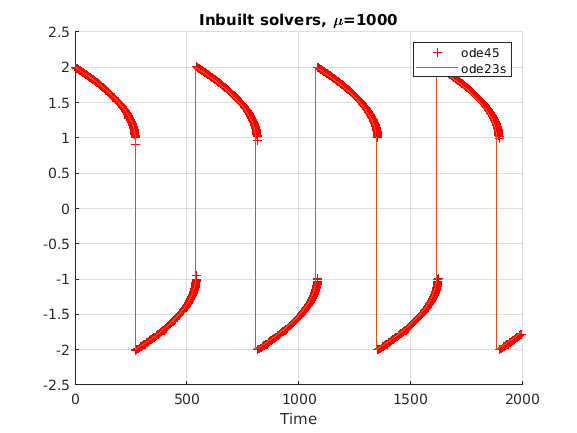

tic
u=1000;
f=@(t,x0) [x0(2), u*(1-x0(1)^2)*x0(2)-3*x0(1)]';
h=@(t,x1) [x1(2), u*(1-x1(1)^2)*x1(2)-3*x1(1)]';
y0=[2;0];
t= [0:0.1:2000]';
hold on
[t0,x1]=ode23s(h,t,y0);
[t0,x0]=ode45(f,t,y0);
plot(t,x0(:,1),'r+')
plot(t,x1(:,1))
legend('ode45','ode23s')
xlabel('Time')
grid()
title("Inbuilt solvers, \mu="+u)

solver_time_complexity=toc

solver_time_complexity = 4.7440